## Three phase system - Time domain representation

clear all; close all;

Definition of the frequency and the points of the vector 'time' for two periods (40 ms)

%% Definició de les tensions (f=50 Hz) w=2*pi*f
w = 2*pi*50;
t = 0:0.04/200:0.04;

Calculation of the voltages

V=1 %rms

V = 1

va = V*sqrt(2)*cos(w*t);
vb = V*sqrt(2)*cos(w*t - 2*pi/3);
vc = V*sqrt(2)*cos(w*t + 2*pi/3);


Plotting the abc functions

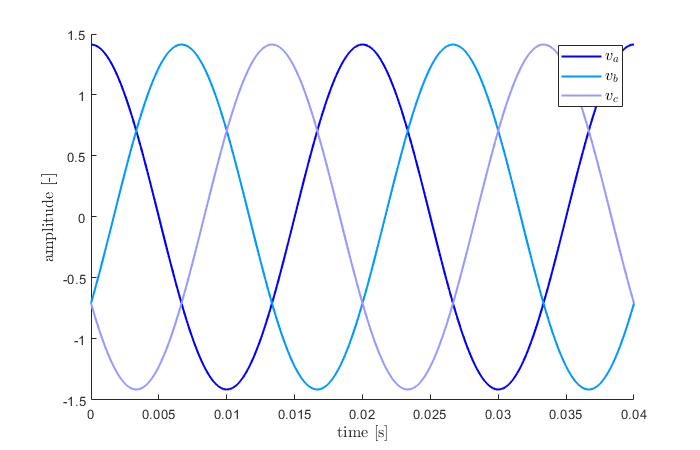

f1 = figure(1);
set(f1, 'Position', [50 500 700 450]);
hold on;
plot(t,va,'LineWidth',1.5,'Color',[0 0 1]);
plot(t,vb,'LineWidth',1.5,'Color',[0 0.6 1]);
plot(t,vc,'LineWidth',1.5,'Color',[0.6 0.6 1]);
ylim([-1.5 1.5]);
l1 = legend('$v_a$','$v_b$','$v_c$');
set(l1,'Interpreter','latex','FontSize',12,'Location','NorthEast');
xlabel('time [s]','Interpreter','latex','FontSize',12);
ylabel('amplitude [-]','Interpreter','latex','FontSize',12);